# LDA PARAMETER SWEEP

## Configure

regMap=nexon.console.NPXLS.shanks.shank1.regMap;
% regSel = cellstr(["STN","VPL","VPM","CA3","SSp-tr5","SSp-tr6a","CA1","CA2","PO"])';
regSel = cellstr(["alv"])';
chanSel = arrayfun(@(reg) regMap.channel(ismember(regMap.region, reg)), regSel, "UniformOutput",false);
chanSel = cellfun(@(C) flip(cat(2,C{:})), chanSel,"UniformOutput",false);
regSel = strrep(regSel,"-","_");
% RES=struct();
for i = 1:length(regSel)
    reg = regSel{i};
    chan = chanSel{i};
    TEST_PRED=[];
    for j = 1:length(mdlObjs)
        foldID=sprintf("F%d",j);
        mdlObj_cv=mdlObjs{j};
        mdlObj_cv.cfg.dmCfg.chanSel=chan;
        mdlObj_cv.trainMask = trainMasks{j};
        % train the model (on a subpartition) 
        mdlObj_cv.STAT=mdlObj.STAT;
        mdlObj_cv.fit(); 
        RES.(reg).(foldID).W_features = double(mdlObj_cv.model.coef_);
        % save the test data (TEST.data)
        % if model IS predictor
            % predict (TEST.predictions)
        % if model HAS predictor
            % generate outputs and train predictor
        % predict
        TEST_pred = mdlObj_cv.predictTEST();
        TEST_PRED = [TEST_PRED; TEST_pred];
    end
    mdlObj.TEST.STAT=TEST_PRED;            
    % score (TEST.CM 'confusion matrix') 
    Y_true=mdlObj.TEST.STAT.(mdlObj.targetVar);
    TF_preds = mdlObj.TEST.STAT.prediction;
    % [TF_probs, TF_scores] = cellfun(@(DF) max(mean(DF.df,1)), TF_preds, "UniformOutput",false);
    [TF_probs] = cellfun(@(DF) (mean(DF.df,1)), TF_preds, "UniformOutput",false);
    TF_probs=cat(1,TF_probs{:});
    L=TF_preds{1}.ax.(mdlObj.targetVar);
    Scores = cellfun(@(score) L(score), TF_scores);            
    RES.(reg).rocObj = rocmetrics((nexOp_labelEncode(Y_true)), TF_probs, [1:4], NumBootstraps=1000);
    figure; plot(RES.(reg).rocObj); title(reg)
    RES.(reg).TEST_PRED=TEST_PRED;
end

## CV


TEST_PRED=[];
for i = 1:length(mdlIDs_cv)
    mdlID = mdlIDs_cv{i};
    mdlObj_cv = mdlObj.CV.(mdlID);
    % mdlObj_cv.STAT = mdlObj.STAT;
    mdlObj_cv.trainMask = trainMasks{i};
    % train the model (on a subpartition) 
    mdlObj_cv.fit(); 
    RES.(reg).W_features = double(mdlObj_cv.model_coef_);
    % save the test data (TEST.data)
    % if model IS predictor
        % predict (TEST.predictions)
    % if model HAS predictor
        % generate outputs and train predictor
    % predict
    TEST_pred = mdlObj_cv.predictTEST();
    TEST_PRED = [TEST_PRED; TEST_pred];
    % mdlObj_cv.predictor.predict();
   
end



## Results

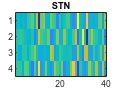

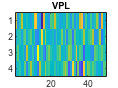

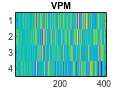

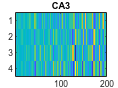

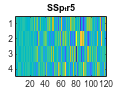

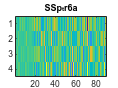

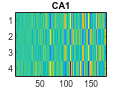

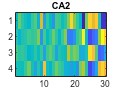

regFields = fieldnames(RES);
for i = 1:length(regFields)
    reg = regFields{i};
    folds = convertCharsToStrings(fieldnames(RES.(reg)));
    folds = folds(contains(folds,"F"));
    W_avg = [];
    for j = 1:length(folds)
        fold = folds{j};
        W = RES.(reg).(fold).W_features;
        W_avg = cat(3, W_avg, W);
    end
    W_avg = mean(W_avg,3);
    figure; imagesc(W_avg); title(reg);
end

## TIME WINDOW

% make predictions with limited temporal context
% tCond = [-1:0];
% tCond = [-1:0];
tCond = [-0.5:0.5];
regFields = fieldnames(RES);
figure;
tl = tiledlayout(2,ceil(length(regFields)/2));
for i = 1:length(regFields)
    ax_tl = nexttile(tl);
    reg = regFields{i};
    TEST_PRED = RES.(reg).TEST_PRED;
    prediction = TEST_PRED.prediction;
    % prediction_window = cellfun(@(DF) DF.df(ismember(tCond,DF.ax.t),:), prediction, "UniformOutput", false);
    prediction_window = cellfun(@(DF) DF.df((DF.ax.t>min(tCond)) & (DF.ax.t<max(tCond)),:), prediction, "UniformOutput", false);
    prediction_mean = cellfun(@(p) mean(p,1), prediction_window, "UniformOutput", false);
    TF_probs = cat(1, prediction_mean{:});    
    Y_true=TEST_PRED.(mdlObj.targetVar);
    rocObj = rocmetrics((nexOp_labelEncode(Y_true)), TF_probs, [1:4], NumBootstraps=1000);
    plot(ax_tl,rocObj); title(reg)
end